# 1CWK50 optional template

This is an **optional** template which you can use for your 1CWK50 investigation if it is helpful. Full instructions on how to submit are available in the assignment specification on Moodle ("Submission" section). Make sure you read them carefully, and that you test your final submission thoroughly before uploading it to Moodle. No additional files can be accepted after the deadline has passed.

## 1. Filesize-based features

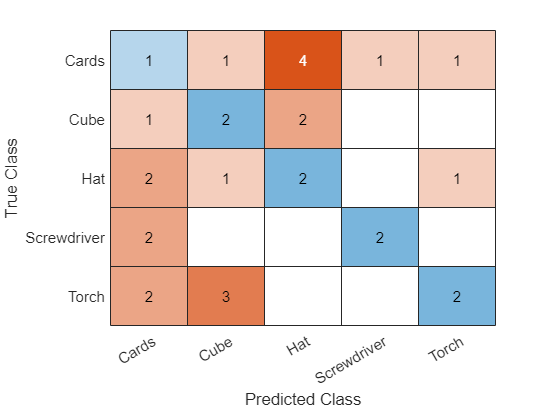

%% NOTE!!!!!!: I found as this file is so big it may be glitchy
%and show incorrect results therefore you may have to run each section at a
%time and maybe a few times (NOTE: my comments where i put the accuracy
%percentage are CORRECT if its anything other than that its a glitch)

%------------------ TASK 1 ----------------

%load data sheet for processing
data = readcell('MerchData.csv');

%delete the header title row as the ML does not process this
data(1:1:1, :) = [];

%shuffle cell array for the best accuracy to ensure we will get
%representative samples
shuffle = data(randperm(size(data, 1)), :);

% split data 60/40 to enable cross testing of data
tempTest = round(0.4 * size(shuffle,1));

%isolate numerical for the classifier to learn
test_examples = shuffle(1:1:tempTest, :);
train_examples = shuffle(tempTest+1:1:end, :);

%set index where the labels are in the table to
label_index = 2;

%isolate labeled data to enable the classifer to identify where numerical
%data belongs to
test_labels = categorical(test_examples(:, label_index));
train_labels = categorical(train_examples(:, label_index));

%convert cell data into useable numerical data for the classifier to read
test_examples = cell2mat(test_examples(:, 1:end~=label_index));
train_examples = cell2mat(train_examples(:, 1:end~=label_index));

%load KNN classifer with k = 3 (nearest neighbor)
kNN = fitcknn(train_examples,train_labels,"NumNeighbors",3);

%returns an array predicted labels by the classifer based on the neasest
%neighbors
predictions = predict(kNN,test_examples);

%creates a matrix of predicted labels and test labels overlapped and
% a array of unique labels in order for use in visualsation and accuracy
% plotting
[c, order] = confusionmat(test_labels, predictions);

%visualises a confusion matrix using predited labels from the classifer to
%show the user whtch and how many predictions it made
confusionchart(test_labels, predictions);


%creates a accuracy in the form of a percentage from the confusion matrix
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 30



%----------------%my version of KNN --------------------------------------
my_knn = knn_fit(train_examples,train_labels,3);
my_predict = knn_predict(my_knn,test_examples);

[c, order] = confusionmat(test_labels, my_predict);
p2 = sum(diag(c)) / sum(c(1:1:end)) * 100

p2 = 30


%exact same accuracy and same K value
knn_same = isequal(p2,p)

knn_same = logical
   1



%----- Finding Best Version of K ---------
grow = [];
%empty array for growing our K values and accuracy percentages

%loops over our classifier the the same number of times as our testing
%example size (Max possible K value)
for i=1:2:size(test_examples,1)

    kNN = fitcknn(train_examples,train_labels, 'NumNeighbors', i);
    predictions = predict(kNN,test_examples);
    
    
    [c, order] = confusionmat(test_labels, predictions);
    p1 = sum(diag(c)) / sum(c(1:1:end)) * 100;

    grow(end+1,:) = [i,p1];
    %index (or K value) and percentage score is stored for comparison

end

%finds an array of highest percentages for optimal K
pcent = max(grow(:,2))

pcent = 53.3333


%creates a logical array of the higest percentages indexing the original
%array
index1 = grow(:,2) == pcent;

%array of all K's with the highest percentages (in order)
k = grow(index1,1);

k =     15
    17



%finds the index of the most optimal K which compinsates for over and underfitting by
%getting the half way point of all of the Ks
k_best = round(size(k,2) \ 2);

%displays the most optimal K
k_best = k(k_best,:)

k_best = 17



%%---my_ version of K with optimal K value-----%%

my_knn = knn_fit(train_examples,train_labels,k_best);
my_predict = knn_predict(my_knn,test_examples);

[c, order] = confusionmat(test_labels, my_predict);
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 53.3333


isequal(pcent,p)

ans = logical
   1


%matlab built in KNN vs my_Knn accuracy SAME :)

%---- Other classifier ------ (no parameters set to match KNN simplicity)

%Naive Bayes classifier 

%diffrent call apposed to KNN
NBC = fitcnb(train_examples,train_labels);
predictions = predict(NBC,test_examples);

[c, order] = confusionmat(test_labels, predictions);
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 36.6667


%decison tree

tree = fitctree(train_examples,train_labels);
predictions = predict(tree,test_examples);

[c, order] = confusionmat(test_labels, predictions);
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 33.3333


%(SVM) classifier 

SVM = fitcecoc(train_examples,train_labels);
predictions = predict(SVM,test_examples);

[c, order] = confusionmat(test_labels, predictions);
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 40

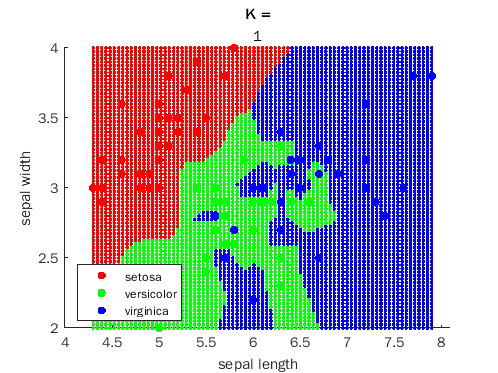

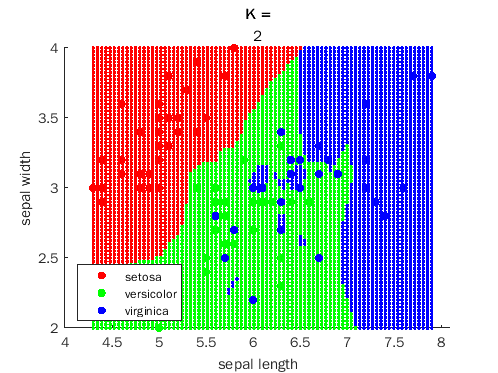

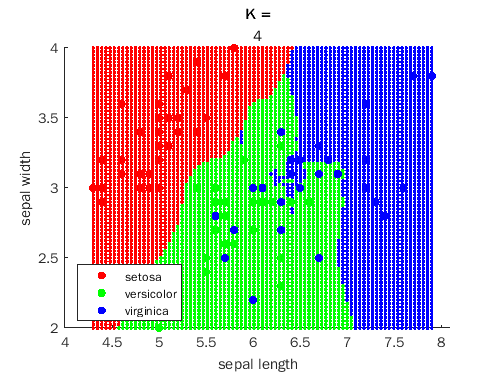

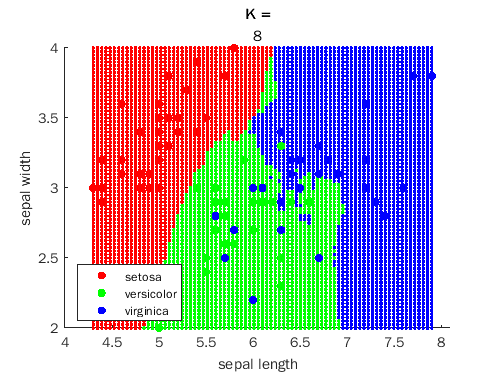

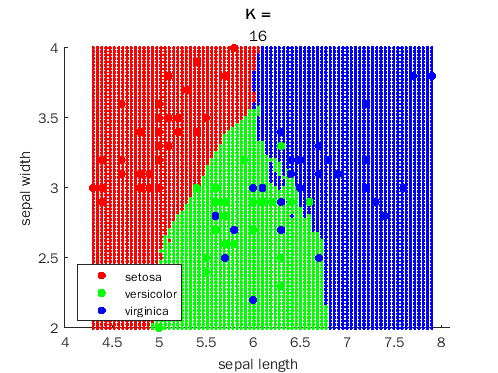

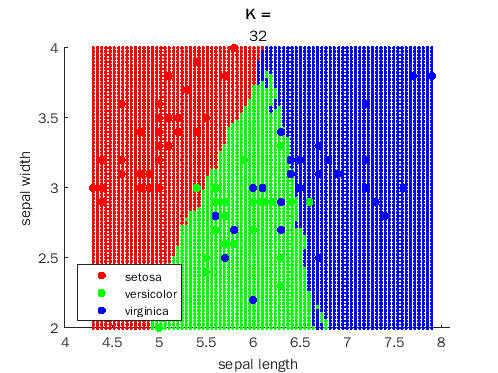

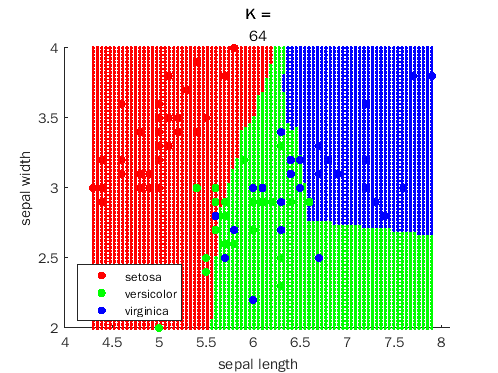

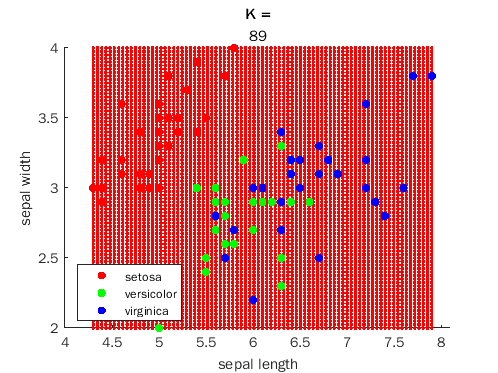

%-------------- task 2 extension visulation --------------------
rng(0);

mycellarray = readcell('iris.csv');

mycellarray(1:1:1, :) = [];

shuffle = mycellarray(randperm(size(mycellarray, 1)), :);

tempTest = round(0.4 * size(shuffle,1));

shuffle(:,[3,4]) = [];
%removed the 3rd and 4th column and left as data isnt needed for plotting

train_examples = shuffle(tempTest+1:1:end, :);

label_index = 3;
%label location for this data is diffrent to TASK 1

train_labels = categorical(train_examples(:, label_index));
train_examples = cell2mat(train_examples(:, 1:end~=label_index));

%https://uk.mathworks.com/help/stats/classification-example.html
%ideas from this as i was struggling to create the grid of data using loops

%takes the max length value for the limit of the increment
maxLenVal = max(train_examples(:,1));
%takes the min length value for the base value of incrmenting
minLenVal = min(train_examples(:,1));


rangeLen = (maxLenVal - minLenVal) / 80;
%calculating the length range for the increment jump when creating a grid
%array

%same as above howver is using the Width data
maxWdthVal = max(train_examples(:,2));
minWdthVal = min(train_examples(:,2));
rangeWth = (maxWdthVal - minWdthVal) / 80;

maxK = size(train_examples,1) -1;
%finds maxiumum K value -1 to get the highest K possible

for i=[1 2 4 8 16 32 64 maxK]
    %loops 8 times and 'i' becomes the K value each time

    kNN = fitcknn(train_examples,train_labels, 'NumNeighbors', i);

    %same as a for loop but easier as no other data is needed within the
    %loop
    length = minLenVal:rangeLen:maxLenVal;
    width = minWdthVal:rangeWth:maxWdthVal;
    %creates an array of length and width values for the grid data

    [length,width] = meshgrid(length,width);
    %meshgrid function creates a grid the length and width of both being equal to
    %the inputs
    %NOTE: length is duplicated vertically and width is duplicated horizontailly

    test_examples = [length(:) width(:)];
    %new test examples are created to be the same width dimensions as the orginal
    %test_examples with the length being the same as mesh grid
    
    prediction = predict(kNN,test_examples);
    %creates a 2d array of predicitons to be the size of the grid data.
    
    figure();
    hold on
    %stops figure from being overwritten by the loop

    gscatter(length(:), width(:),prediction,'rgb')
    gscatter(train_examples(:,1), train_examples(:,2),train_labels)
    %layered the original data over the grid of points

    xlabel('sepal length')
    ylabel('sepal width')
    title('K =',i)
    %labels the data for visualisation to the user
    
end

## Loading and preparing datasets

% check the dataset is present:

if ~exist('./MerchData', 'dir')
    error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
end

rng(0); % re-seed the random number for reproducible results

imds = imageDatastore('MerchData','IncludeSubfolders', true,'LabelSource','foldernames');

%splits the image datastore and randomises them to ensure we get
%represntative samples
[training, testing] = splitEachLabel(imds, 0.6, 'randomize');


## 2. Brightness-based features

%------------------ TASK 3 --------------------%

train_labels = training.Labels;
%creates an array of labels from the training image split within the
%imageDataStore for the classifier

train_examples = [];
%empty array used for growing in a loop

%loops until no indexed data is present
while hasdata(training)
    im = training.read();
    %collects image at each loop pass for the brightess function
    train_examples(end+1,:) = get_brightness(im);
    %expands a 2d array vertically for for the classifier
end

test_labels = testing.Labels;
test_examples = [];

while hasdata(testing)
    im = testing.read();
    test_examples(end+1,:) = get_brightness(im);
end

kNN = fitcknn(train_examples, train_labels , 'NumNeighbors', 3);
predictions = predict(kNN,test_examples);

[c, order] = confusionmat(test_labels, predictions);
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 46.6667


%46.6667 with built in im2gray
%46.6667 with my_im2gray
%uncommnet my_ in get_brightness to test


## 3. Edge-based features

%---------------------- TASK 4 -------------------%

training.reset
testing.reset
%resets the indexing so the loops can start from zero again

train_labels = training.Labels;
train_examples = [];

while hasdata(training)
    im = im2gray(training.read());
    %converts each training image to 1 layer grayscale
    train_examples(end+1,:) = get_edges(im);
end 

test_labels = testing.Labels;
test_examples = [];

while hasdata(testing)
    im = im2gray(testing.read());
    test_examples(end+1,:) = get_edges(im);
end

kNN = fitcknn(train_examples,train_labels,"NumNeighbors",3);
predictions = predict(kNN,test_examples);
    
[c, order] = confusionmat(test_labels, predictions);
    
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 53.3333


%53.3333 with matlab imgradientxy
%53.3333 with my_imgradientxy
%uncomment call to my_ in get_edges to test accuracy



## 4. HOG-based features 

training.reset
train_labels = training.Labels;
train_examples =[];

while hasdata(training)
    im = im2gray(training.read());
    train_examples(end+1,:) = get_hogs(im);
end

testing.reset
test_labels = testing.Labels;
test_examples =[];

while hasdata(testing)
    im = im2gray(testing.read());
    test_examples(end+1,:) = get_hogs(im);
end

kNN = fitcknn(train_examples, train_labels , 'NumNeighbors', 3);
predictions = predict(kNN, test_examples);

[c, order] = confusionmat(test_labels, predictions);
    
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 56.6667


%63.3333 accuracy with built in function
%56.6667 with my_extractHOFFeatures (no overlapping features etc.)
%NOTE: I had higher accuracy however the bins had to start from -170
%instead of -180 and made the bag less accurate




## 5. BoVW-based features

%---------------- TASK 7 ---------------------%

words = bagOfFeatures(imds);

Creating Bag-Of-Features.
-------------------------
* Image category 1: MathWorks Cap
* Image category 2: MathWorks Cube
* Image category 3: MathWorks Playing Cards
* Image category 4: MathWorks Screwdriver
* Image category 5: MathWorks Torch
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 75 images...done. Extracted 235200 features.

* Keeping 80 percent of the strongest features from each category.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 188160
* Number of clusters          : 500
* Initializing cluster centers...100.00%.
* Clustering...completed 23/100 iterations (~0.47 seconds/iteration)...converged in 23 iterations.

* Finished creating Bag-Of-Features



%creates a bag of visual words from the entire imageDataStore for use in of
%the classifier

testing.reset;
training.reset;

train_labels = training.Labels;
train_examples=[];

while hasdata(training)
    im = im2gray(training.read());
    train_examples(end+1,:) = words.encode(im);
end

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features



test_labels = testing.Labels;
test_examples =[];


while hasdata(testing)
    im = im2gray(testing.read());
    test_examples(end+1,:) = words.encode(im);
end

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.

Encoding images using Bag-Of-Features


kNN = fitcknn(train_examples, train_labels , 'NumNeighbors', 3);
predictions = predict(kNN, test_examples);

[c, order] = confusionmat(test_labels, predictions);
    
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 83.3333


%create own version of above (get_words + get_bag) 

training.reset
trainHog =[];

while hasdata(training)
    im = im2gray(training.read());
    trainHog(end+1,:) = get_hogs(im);
end

words = my_kmeans(trainHog,500);

words =     0.0009    0.0013    0.0014    0.0041    0.0045    0.0002    0.0010    0.0012    0.0006
    0.0003    0.0009    0.0025    0.0006    0.0016    0.0034    0.0024         0    0.0018
    0.1327    0.0014    0.0721    0.0018    0.0093    0.0042    0.0120    0.0003    0.0011
    0.0252    0.0011    0.0282    0.0009    0.0037    0.0037    0.0017    0.0020    0.0019
         0    0.0001    0.0011    0.0014    0.0014         0    0.0012    0.0005         0
    0.0016    0.0051    0.0397    0.0019    0.0020    0.0005    0.0741    0.0028    0.0013
    0.0002    0.0007    0.0005    0.0043    0.0010    0.0036    0.0010    0.0011    0.0009
    0.0011    0.0118    0.0036    0.0176    0.0111    0.0179    0.0237    0.0039    0.0014
    0.0011         0         0    0.0003    0.0008    0.0057         0    0.0011    0.0038
    0.0046    0.0242    0.0103    0.0016    0.0135    0.0056    0.0020    0.0006    0.0249



train_labels = training.Labels;
train_bags = [];

training.reset;

while hasdata(training)
    im = training.read();
    h = get_hogs(im);
    train_bags(end+1,:) = get_bag(h,words);
end

test_labels = testing.Labels;
test_bags =[];

testing.reset;

while hasdata(testing)
    im = testing.read();
    h = get_hogs(im);
    test_bags(end+1,:) = get_bag(h,words);
end

kNN = fitcknn(train_bags, train_labels , 'NumNeighbors', 3);
predictions = predict(kNN, test_bags);

[c, order] = confusionmat(test_labels, predictions);
   
p1 = sum(diag(c)) / sum(c(1:1:end)) * 100

p1 = 76.6667


%76.667 accuracy with my version of get_bag , kmeans, my_extractHogFeatures
%83.333 accuracy with built in version




## 6. CNN-based features

%load data sheet
data = readcell('MerchData.csv');

%delete the header title row as the ML does not need this
data(1:1:1, :) = [];

%shuffle cell array for best accuracy
shuffle = data(randperm(size(data, 1)), :);

% 60% training / 40% testing data
tempTest = round(0.4 * size(shuffle,1));

%isolate numerical and ramdomise for later use
test_examples = shuffle(1:1:tempTest, :);
train_examples = shuffle(tempTest+1:1:end, :);

%set index where the labels are in the table
label_index = 2;

%isolate categorised data into a label variable 
test_labels = categorical(test_examples(:, label_index));
train_labels = categorical(train_examples(:, label_index));

%convert cell data into useable numerical data for the ML
test_examples = cell2mat(test_examples(:, 1:end~=label_index));
train_examples = cell2mat(train_examples(:, 1:end~=label_index));

net = fitcnet(train_examples,train_labels, ...
    'LayerSizes',[3 4],...
    'Activations','sigmoid',...
    'Verbose',1)

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.328014|    0.012976|    0.220801|    0.053807|
|           2|    0.279598|    0.030258|    2.573056|    0.016649|
|           3|    0.252054|    0.092599|    2.140680|    0.004164|
|           4|    0.195511|    0.071343|    1.375182|    0.004177|
|           5|    0.089476|    0.011525|    6.455214|    0.008990|
|           6|    0.065504|    0.012783|    0.809466|    0.002667|
|           7|    0.061982|    0.007777|    2.159190|    0.001773|
|           8|    0.053827|    0.005598|    0.508517|    0.000620|
|           9|    0.045303|    0.006495|    0.820850|    0.000587|
|          10|    0.042395|    0.006154|    0.611541|    0.000589|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [3 4]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [120×7 table]


  Properties, Methods



pred_train_labels = predict(net,train_examples);
pred_test_labels = predict(net,test_examples);

[confusion_train,order_train] = confusionmat(train_labels, pred_train_labels);
[confusion_test,order_test] = confusionmat(test_labels, pred_test_labels);

perf_train = sum(diag(confusion_train)) / sum(confusion_train(1:1:end)) * 100

perf_train = 99.7067

perf_test1 = sum(diag(confusion_test)) / sum(confusion_test(1:1:end)) * 100

perf_test1 = 96.4912


results = [];

for n1 = 2 : 5
    for n2 = 2 : 5
        net = fitcnet(train_examples,train_labels, ...
        'LayerSizes',[n1 n2],...
        'Activations','sigmoid',...
        'Verbose',1)
        
        pred_test_labels = predict(net,test_examples);
        
        [confusion_test,order_test] = confusionmat(test_labels, pred_test_labels);

        
        perf_test = sum(diag(confusion_test)) / sum(confusion_test(1:1:end)) * 100
        results(end+1,:) = [n1 n2 perf_test];

    end
end

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.337701|    0.047440|    0.150620|    0.005018|
|           2|    0.328105|    0.008350|    0.211253|    0.004059|
|           3|    0.326542|    0.012304|    0.098897|    0.001536|
|           4|    0.293926|    0.078912|    2.110273|    0.000569|
|           5|    0.241294|    0.080236|   14.324201|    0.001095|
|           6|    0.107123|    0.032392|    1.192243|    0.000565|
|           7|    0.067169|    0.022074|    5.749522|    0.000570|
|           8|    0.058844|    0.021715|    3.675943|    0.000724|
|           9|    0.052839|    0.011470|    0.332196|    0.000627|
|          10|    0.048223|    0.006262|    0.907463|    0.000575|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [2 2]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [217×7 table]


  Properties, Methods


perf_test = 97.3684

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.323209|    0.028283|    0.084806|    0.000772|
|           2|    0.315456|    0.020267|    0.226624|    0.000678|
|           3|    0.306284|    0.027184|    0.346396|    0.001156|
|           4|    0.273636|    0.155374|    6.407309|    0.000681|
|           5|    0.192937|    0.107435|    0.382493|    0.000660|
|           6|    0.079441|    0.065951|    3.516146|    0.000642|
|           7|    0.056024|    0.008772|    2.646032|    0.000693|
|           8|    0.053952|    0.007034|    0.300713|    0.000653|
|           9|    0.048129|    0.013468|    2.561455|    0.000668|
|          10|    0.042638|    0.005660|    0.351407|    0.000670|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [2 3]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [64×7 table]


  Properties, Methods


perf_test = 97.3684

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.330111|    0.017605|    0.071923|    0.000725|
|           2|    0.326876|    0.005481|    0.124094|    0.000803|
|           3|    0.325027|    0.010761|    0.103555|    0.000708|
|           4|    0.314755|    0.043173|    0.819536|    0.000644|
|           5|    0.292192|    0.063448|    1.472330|    0.001137|
|           6|    0.153796|    0.048755|   15.994977|    0.000661|
|           7|    0.120243|    0.014351|    9.295141|    0.000667|
|           8|    0.110189|    0.011311|    3.033290|    0.000634|
|           9|    0.102058|    0.019397|    7.905499|    0.001156|
|          10|    0.095292|    0.004838|    3.815245|    0.000684|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [2 4]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [594×7 table]


  Properties, Methods


perf_test = 96.0526

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.318725|    0.026279|    0.151633|    0.001311|
|           2|    0.308381|    0.013280|    0.199101|    0.000778|
|           3|    0.299906|    0.025328|    0.228074|    0.000813|
|           4|    0.268120|    0.064745|    1.046171|    0.000724|
|           5|    0.211921|    0.084401|    1.960030|    0.000675|
|           6|    0.091913|    0.028006|    6.612611|    0.000686|
|           7|    0.070758|    0.012301|    1.100865|    0.000740|
|           8|    0.057756|    0.007058|    0.814603|    0.000650|
|           9|    0.050623|    0.005940|    0.918834|    0.000748|
|          10|    0.048346|    0.005343|    0.473599|    0.000668|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [2 5]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [93×7 table]


  Properties, Methods


perf_test = 96.4912

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.346366|    0.073098|    0.175050|    0.000647|
|           2|    0.320065|    0.010435|    0.409923|    0.000597|
|           3|    0.311534|    0.019987|    0.286871|    0.000903|
|           4|    0.289416|    0.104639|    4.518061|    0.000525|
|           5|    0.231388|    0.073539|    0.434966|    0.000530|
|           6|    0.137412|    0.034006|    3.513982|    0.000555|
|           7|    0.124028|    0.019224|    0.469135|    0.000565|
|           8|    0.101268|    0.007354|    1.515744|    0.000570|
|           9|    0.077727|    0.017386|    1.372522|    0.000550|
|          10|    0.065339|    0.008029|    3.054569|    0.001260|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [3 2]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [78×7 table]


  Properties, Methods


perf_test = 96.4912

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.336818|    0.033616|    0.110409|    0.000552|
|           2|    0.329236|    0.005943|    0.214435|    0.000546|
|           3|    0.325674|    0.004262|    0.206817|    0.001418|
|           4|    0.303943|    0.026524|    1.646578|    0.000565|
|           5|    0.221507|    0.073421|    6.438068|    0.000666|
|           6|    0.192285|    0.066645|   17.809729|    0.000636|
|           7|    0.136815|    0.092009|    4.418148|    0.000663|
|           8|    0.130927|    0.038963|    1.579752|    0.000632|
|           9|    0.116040|    0.027950|    1.217934|    0.000634|
|          10|    0.106620|    0.009931|    1.861693|    0.001173|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [3 3]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [159×7 table]


  Properties, Methods


perf_test = 96.0526

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.385254|    0.112755|    0.477237|    0.000564|
|           2|    0.329356|    0.017564|    0.516215|    0.000548|
|           3|    0.322386|    0.016879|    0.105223|    0.000575|
|           4|    0.275706|    0.063837|    1.591649|    0.000547|
|           5|    0.221117|    0.033398|    1.195054|    0.000954|
|           6|    0.113396|    0.021814|    9.244768|    0.000546|
|           7|    0.069860|    0.018022|    1.767776|    0.000544|
|           8|    0.056059|    0.007898|    0.483712|    0.000565|
|           9|    0.051296|    0.003051|    0.441294|    0.000571|
|          10|    0.049063|    0.003180|    0.387645|    0.000565|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [3 4]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [85×7 table]


  Properties, Methods


perf_test = 97.3684

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.334288|    0.016268|    0.083479|    0.000544|
|           2|    0.323210|    0.014741|    0.292034|    0.000574|
|           3|    0.315348|    0.019723|    0.269443|    0.000631|
|           4|    0.284230|    0.025117|    1.186739|    0.000620|
|           5|    0.158071|    0.025714|    4.757150|    0.000651|
|           6|    0.126453|    0.021363|   12.795881|    0.001107|
|           7|    0.079149|    0.008256|    1.565270|    0.000629|
|           8|    0.068893|    0.007687|    1.700018|    0.000641|
|           9|    0.065138|    0.013680|    2.109780|    0.000627|
|          10|    0.060522|    0.005913|    0.904603|    0.000648|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [3 5]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [113×7 table]


  Properties, Methods


perf_test = 96.4912

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.345415|    0.025861|    0.085936|    0.000552|
|           2|    0.331877|    0.019524|    0.345136|    0.000557|
|           3|    0.324049|    0.027888|    0.281099|    0.000535|
|           4|    0.298448|    0.034080|    1.064077|    0.000528|
|           5|    0.111491|    0.013567|    8.012158|    0.000905|
|           6|    0.053709|    0.008730|    5.509124|    0.000573|
|           7|    0.047820|    0.007299|    1.140292|    0.000533|
|           8|    0.043371|    0.006385|    0.426928|    0.000533|
|           9|    0.038426|    0.003130|    0.591014|    0.000540|
|          10|    0.035179|    0.004091|    0.789211|    0.001053|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [4 2]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [41×7 table]


  Properties, Methods


perf_test = 97.8070

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.345863|    0.034938|    0.143139|    0.000538|
|           2|    0.335242|    0.011283|    0.241886|    0.000547|
|           3|    0.327212|    0.010344|    0.306116|    0.001290|
|           4|    0.292245|    0.022130|    2.472029|    0.000531|
|           5|    0.170558|    0.040190|    6.232210|    0.000896|
|           6|    0.154347|    0.021302|   36.618048|    0.000536|
|           7|    0.151332|    0.040135|    2.463935|    0.000556|
|           8|    0.113479|    0.015504|    6.872582|    0.000546|
|           9|    0.102363|    0.028040|    9.870701|    0.000907|
|          10|    0.082583|    0.016082|    7.036425|    0.000546|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [4 3]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [76×7 table]


  Properties, Methods


perf_test = 96.0526

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.389737|    0.125428|    0.433143|    0.000566|
|           2|    0.320685|    0.020080|    0.618271|    0.000722|
|           3|    0.315014|    0.013497|    0.102772|    0.000615|
|           4|    0.274430|    0.100160|    1.622496|    0.000557|
|           5|    0.212129|    0.066571|    0.905217|    0.000973|
|           6|    0.115077|    0.021688|    6.914624|    0.000544|
|           7|    0.071723|    0.008983|    0.991604|    0.000565|
|           8|    0.054930|    0.004937|    0.996683|    0.000570|
|           9|    0.049916|    0.003224|    0.581547|    0.000540|
|          10|    0.038816|    0.003857|    2.054946|    0.000544|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [4 4]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [178×7 table]


  Properties, Methods


perf_test = 95.6140

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.364867|    0.098925|    0.426659|    0.000559|
|           2|    0.319354|    0.011520|    0.445335|    0.000573|
|           3|    0.296243|    0.019210|    0.437925|    0.001289|
|           4|    0.177745|    0.026795|    3.346337|    0.000542|
|           5|    0.077789|    0.012444|    7.418642|    0.000586|
|           6|    0.047439|    0.005141|    2.199968|    0.000548|
|           7|    0.041665|    0.002576|    0.591511|    0.000556|
|           8|    0.038468|    0.003608|    0.685345|    0.000545|
|           9|    0.035814|    0.001557|    0.619305|    0.000549|
|          10|    0.033773|    0.004309|    0.995319|    0.000597|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [4 5]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [192×7 table]


  Properties, Methods


perf_test = 95.1754

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.327475|    0.010963|    0.168288|    0.001499|
|           2|    0.271416|    0.030201|    2.930774|    0.000630|
|           3|    0.132486|    0.035955|    4.656584|    0.000650|
|           4|    0.115243|    0.025065|   10.392238|    0.000641|
|           5|    0.051273|    0.007906|    1.425974|    0.000607|
|           6|    0.043658|    0.006622|    0.628819|    0.000624|
|           7|    0.038235|    0.004525|    0.886560|    0.000629|
|           8|    0.034584|    0.003397|    0.549353|    0.000644|
|           9|    0.031806|    0.003177|    0.939152|    0.000664|
|          10|    0.028378|    0.001638|    1.570846|    0.000648|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [5 2]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [32×7 table]


  Properties, Methods


perf_test = 96.9298

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.319554|    0.054296|    0.192569|    0.000545|
|           2|    0.286700|    0.018710|    0.435815|    0.000573|
|           3|    0.269143|    0.035466|    0.342575|    0.000553|
|           4|    0.195533|    0.080827|    2.063260|    0.000536|
|           5|    0.129436|    0.055447|    1.823174|    0.000676|
|           6|    0.077159|    0.011551|    3.072341|    0.000567|
|           7|    0.058278|    0.010351|    0.631822|    0.000977|
|           8|    0.054502|    0.007027|    0.978996|    0.001301|
|           9|    0.048277|    0.005468|    0.344669|    0.000564|
|          10|    0.045798|    0.006880|    1.294127|    0.000569|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [5 3]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [40×7 table]


  Properties, Methods


perf_test = 94.7368

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.328074|    0.054863|    0.290323|    0.000634|
|           2|    0.305449|    0.016020|    0.284890|    0.000609|
|           3|    0.295474|    0.026732|    0.189527|    0.000565|
|           4|    0.220731|    0.088678|    2.383349|    0.000572|
|           5|    0.168279|    0.075875|    1.291754|    0.000551|
|           6|    0.075188|    0.009596|    4.873751|    0.000591|
|           7|    0.066911|    0.008114|    0.257370|    0.000584|
|           8|    0.050102|    0.006421|    1.810673|    0.000555|
|           9|    0.042468|    0.003478|    0.717772|    0.000558|
|          10|    0.040188|    0.003273|    0.344709|    0.000566|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [5 4]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [43×7 table]


  Properties, Methods


perf_test = 97.3684

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.331026|    0.028254|    0.130670|    0.000676|
|           2|    0.322385|    0.017498|    0.183012|    0.000609|
|           3|    0.313539|    0.027888|    0.245069|    0.000556|
|           4|    0.258520|    0.080299|    1.707707|    0.000622|
|           5|    0.134323|    0.044205|    5.839984|    0.000582|
|           6|    0.108767|    0.075259|    6.409608|    0.000589|
|           7|    0.060751|    0.016840|    2.332752|    0.000634|
|           8|    0.053334|    0.013343|    0.482574|    0.000588|
|           9|    0.045929|    0.007181|    0.772865|    0.000603|
|          10|    0.039622|    0.005568|    0.486546|    0.000621|
|=============================================================

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Benign    Malignant]
           ScoreTransform: 'none'
          NumObservations: 341
               LayerSizes: [5 5]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [49×7 table]


  Properties, Methods


perf_test = 95.6140


results=results(results(:,3)==max(results(:,3)),:)

ans =     4.0000    2.0000   97.8070


%displays and stores optimal Node 1 and 2 aswell as percentage accuracy

%finding a optimal node improves preformance by:
diff = results(1,3) - perf_test1

diff = 0.8772


%---------------------OPTIMAL nodes-----------------%

net = fitcnet(train_examples,train_labels, ...
    'LayerSizes',[n1 n2],...
    'Activations','sigmoid',...
    'Verbose',1)

|================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  |
|            |            |            |            | Time (sec) |
|================================================================|
|           1|    0.332126|    0.020784|    0.051892|    0.000464|
|           2|    0.320984|    0.001734|    0.506669|    0.000448|
|           3|    0.320901|    0.000399|    0.042481|    0.000406|
|           4|    0.320898|    0.000059|    0.007251|    0.000398|
|           5|    0.320898|    0.000002|    0.001169|    0.000396|
|           6|    0.320898|    0.000000|    0.000039|    0.000577|
|================================================================|


net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Cards    Cube    Hat    Screwdriver    Torch]
           ScoreTransform: 'none'
          NumObservations: 45
               LayerSizes: [5 5]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [6×7 table]


  Properties, Methods



pred_train_labels = predict(net,train_examples);
pred_test_labels = predict(net,test_examples);

[confusion_train,order_train] = confusionmat(train_labels, pred_train_labels);
[confusion_test,order_test] = confusionmat(test_labels, pred_test_labels);

perf_train = sum(diag(confusion_train)) / sum(confusion_train(1:1:end)) * 100

perf_train = 22.2222

perf_test1 = sum(diag(confusion_test)) / sum(confusion_test(1:1:end)) * 100

perf_test1 = 16.6667

clear;
%----------------- TASK 8 -----------------------%

% Locate the digit images 
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
% Load them into a image store. This includes labels etc.
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
% We'll need the number of different labels for the network
numLabels = length(unique(sort(imds.Labels)));
% we will need the number of rows and columns of the images in the network
% Note that we can obtain any image by using its index
imageSize = size(readimage(imds,1));
% randomly split the dataset into two, 75% for training and 25% for Test 
rng(0);
[imdsTrain,imdsTest] = splitEachLabel(imds,0.75,'randomize');
% and the number of trainig and Test images:
numTrainImage = length(imdsTrain.Labels);
numTestImage = length(imdsTest.Labels);


% 2. convert the training images into a 2D matrix
train_params = zeros(numTrainImage,imageSize(1)*imageSize(2));
for i = 1 : numTrainImage
    train_params(i,:) = reshape(imdsTrain.read, imageSize(1)*imageSize(2), 1);
end

% 2a and the Test images
test_params = zeros(numTestImage, imageSize(1)*imageSize(2));
for i = 1 : numTestImage
    test_params(i,:) = reshape(imdsTest.read, imageSize(1)*imageSize(2), 1);
end


% Solution:

valid = cell(2,1);
valid{1} = test_params;
valid{2} = imdsTest.Labels;
net = fitcnet(valid{1},valid{2}, ...
    'LayerSizes',[25 20],...
    'Activations','sigmoid',...
    'Verbose',0, ...
    'ValidationData',valid)

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0    1    2    3    4    5    6    7    8    9]
           ScoreTransform: 'none'
          NumObservations: 2500
               LayerSizes: [25 20]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [1000×7 table]


  Properties, Methods



% 6. Get the prediced class memberships for the training and testing data
pred_train_labels = predict(net,train_params);
pred_test_labels = predict(net,test_params);
 
% 7. Get the confusion matrices
[confusion_train,~] = confusionmat(imdsTrain.Labels, pred_train_labels);
[confusion_test,~] = confusionmat(imdsTest.Labels, pred_test_labels);
% 
disp('Training accuracy');

Training accuracy


disp(sum(diag(confusion_train))/sum(sum(confusion_train))*100);

   69.2533




disp('Testing accuracy');

Testing accuracy


disp(sum(diag(confusion_test))/sum(sum(confusion_test))*100);

   85.9600




perform = zeros(3,3);
layer1 = [600 500 400];
layer2 = [15 20 25];

train_oneLabels = net.TrainingHistory.ValidationLoss;

for i = 1 : length(layer1)
    
    for j = 1 : length(layer2)

        perform(i,j) = train_MNISTnn([layer1(i) layer2(j)],train_params,train_oneLabels);
        disp([layer1(i) layer2(j) perform(i,j)]);
        
    end
    
end

  600.0000   15.0000    0.0600

  600.0000   20.0000    0.0600

  600.0000   25.0000    0.0600

  500.0000   15.0000    0.0645

  500.0000   20.0000    0.0645

  500.0000   25.0000    0.0645

  400.0000   15.0000    0.0715

  400.0000   20.0000    0.0715

  400.0000   25.0000    0.0715






% 6. Plot the accuracy
figure;
surf(perform);
xticks(1 : length(layer2));
xticklabels(layer2);
xlabel('Nodes in second layer');
yticks(1 : length(layer1));
yticklabels(layer1);
ylabel('Nodes in first layer');
zlabel('Error - MSE');
title('Test error');

% Find the parameters associated with the lowest error:

[p1,p2] = find(perform==min(min(perform)));
disp(layer1(p1.')); 

   600   600   600



disp(layer2(p2.'));

    15    20    25



disp([perform(p1,p2)]);

    0.0600    0.0600    0.0600
    0.0600    0.0600    0.0600
    0.0600    0.0600    0.0600




n1 = mean(layer1(p1.'))

n1 = 600

n2 = mean(layer2(p2.'))

n2 = 20

valid = cell(2,1);
valid{1} = test_params;
valid{2} = imdsTest.Labels;
net = fitcnet(valid{1},valid{2}, ...
    'LayerSizes',[n1 n2],...
    'Activations','sigmoid',...
    'Verbose',0)

net =   ClassificationNeuralNetwork
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0    1    2    3    4    5    6    7    8    9]
           ScoreTransform: 'none'
          NumObservations: 2500
               LayerSizes: [600 20]
              Activations: 'sigmoid'
    OutputLayerActivation: 'softmax'
                   Solver: 'LBFGS'
          ConvergenceInfo: [1×1 struct]
          TrainingHistory: [630×7 table]


  Properties, Methods



% 6. Get the prediced class memberships for the training and testing data
pred_train_labels = predict(net,train_params);
pred_test_labels = predict(net,test_params);
 
% 7. Get the confusion matrices
[confusion_train,~] = confusionmat(imdsTrain.Labels, pred_train_labels);
[confusion_test,~] = confusionmat(imdsTest.Labels, pred_test_labels);

disp('Training accuracy');

Training accuracy


disp(sum(diag(confusion_train))/sum(sum(confusion_train))*100);

   87.6400




disp('Testing accuracy');

Testing accuracy


disp(sum(diag(confusion_test))/sum(sum(confusion_test))*100);

   100



% first the training options  
options = trainingOptions('sgdm', ...
    'MaxEpochs',16, ...
    'InitialLearnRate',0.005, ...
    'ValidationData',imdsTest,...
    'ValidationFrequency',10,...
    'ValidationPatience',2, ...
    'Verbose',true, ...
    'VerboseFrequency',30, ...
    'Plots','training-progress',...
    'ExecutionEnvironment', 'auto');

layers = [
    imageInputLayer([imageSize 1])

    convolution2dLayer(3,15,'Padding',1)
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',3)

    convolution2dLayer(5,20,'Padding',2)
    batchNormalizationLayer
    reluLayer

    convolution2dLayer(20,7,'Padding',7)
    batchNormalizationLayer
    reluLayer


    fullyConnectedLayer(15)
    fullyConnectedLayer(numLabels)
    softmaxLayer
    classificationLayer];

[net3,info] = trainNetwork(imdsTrain,layers,options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |        9.38% |        9.92% |       2.7973 |       2.5527 |          0.0050 |
|       1 |          10 |       00:00:10 |       36.72% |       39.84% |       1.7517 |       1.7232 |          0.0050 |
|       1 |          20 |       00:00:11 |       58.59% |       56.92% |       1.3500 |       1.3760 |          0.0050 |
|       1 |          30 |       00:00:12 |       70.31% |       70.12% |       1.1629 |   


pred3_train_labels = classify(net3,imdsTrain);
% and also of the validation set
pred3_test_labels = classify(net3,imdsTest);

% Obtain a confusion matrix of the labels (i.e. the counts of each
% (inferred,real) label combination for the two datasets

[confusion3_train,order_train] = confusionmat(imdsTrain.Labels, pred3_train_labels);
[confusion3_test,order_test] = confusionmat(imdsTest.Labels, pred3_test_labels);

% And finally display the accuracy of the classifier (i.e. the fraction of
% images which are correctly labeled by the net.
disp('Training accuracy : ');

Training accuracy : 


disp(sum(diag(confusion3_train))/sum(sum(confusion3_train))* 100) ;

   99.9867



disp('Training accuracy : ');

Training accuracy : 


disp(sum(diag(confusion3_test))/sum(sum(confusion3_test))* 100) ;

   99.6400



%-------------- TASK 9 --------------------%
clear;  % this just removes all the previous variables, please don't remove it.

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
end

rng(0); % please leave this re-seeding of the random number generator in place so we can compare results

% write your code on the lines below:

% SOLUTION:

 % Locate the digit images 
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');

% Load them into a image store. This includes labels etc.
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

% We'll need the number of different labels for the network
numLabels = length(unique(sort(imds.Labels)));
% we will need the number of rows and columns of the images in the network
% Note that we can obtain any image by using its index

% we will need the number of rows and columns of the images in the network

imageSize = size(readimage(imds,1));

rng(0);

[training, testing] = splitEachLabel(imds,0.60,'randomize');


augTrain = augmentedImageDatastore(imageSize, training, 'ColorPreprocessing', 'gray2rgb');
augTest = augmentedImageDatastore(imageSize, testing, 'ColorPreprocessing', 'gray2rgb');


options = trainingOptions('sgdm', ...
    'MaxEpochs',16, ...
    'InitialLearnRate',0.005, ...
    'ValidationData',augTest,...
    'ValidationFrequency',1,...
    'ValidationPatience',3, ...
    'Verbose',true, ...
    'VerboseFrequency',30, ...
    'Plots','training-progress',...
    'ExecutionEnvironment', 'auto');

% then set the model up...
layers = [
    imageInputLayer([imageSize 3])

    convolution2dLayer(3,15,'Padding',1)
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(3,'Stride',3)

    convolution2dLayer(5,20,'Padding',2)
    batchNormalizationLayer
    reluLayer

    convolution2dLayer(20,7,'Padding',7)
    batchNormalizationLayer
    reluLayer


    %fullyConnectedLayer(15)
    fullyConnectedLayer(numLabels)
    softmaxLayer
    classificationLayer];

[net3,info] = trainNetwork(augTrain,layers,options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:14 |        6.25% |       11.28% |       2.9095 |       2.5307 |          0.0050 |
|       1 |           2 |       00:00:15 |        8.59% |       16.48% |       2.4244 |       2.3260 |          0.0050 |
|       1 |           3 |       00:00:16 |       16.41% |       20.35% |       2.2856 |       2.2195 |          0.0050 |
|       1 |           4 |       00:00:17 |       16.41% |       25.00% |       2.3165 |   

% Now use the network to infer the labels of the training images
pred3_train_labels = classify(net3,augTrain);
% and also of the validation set
pred3_test_labels = classify(net3,augTest);

% Obtain a confusion matrix of the labels (i.e. the counts of each
% (inferred,real) label combination for the two datasets
[confusion3_train,order_train] = confusionmat(training.Labels, pred3_train_labels);
[confusion3_test,order_test] = confusionmat(testing.Labels, pred3_test_labels);
% And finally display the accuracy of the classifier (i.e. the fraction of
% images which are correctly labeled by the net.
disp('Training accuracy : ');

Training accuracy : 


disp(sum(diag(confusion3_train))/sum(sum(confusion3_train))* 100) ;

   98.8333



disp('Training accuracy : ');

Training accuracy : 


disp(sum(diag(confusion3_test))/sum(sum(confusion3_test))* 100) ;

   97.3000



lay = net3.Layers(2,1).Weights();

OutImage = uint8(255 * lay(:,:,:));

for i = 1 : 30
    subplot(5,6,i);
    
    imshow(OutImage(i))
    % imShow each of them here...
end

% Solution:
train_labels = training.Labels;
test_labels = testing.Labels;

kNN = fitcknn(featuresTrain, train_labels , 'NumNeighbors', 3);
predictions = predict(kNN, featuresTest);

[c, order] = confusionmat(test_labels, predictions);
   
p = sum(diag(c)) / sum(c(1:1:end)) * 100

pred_test2_labels = classify(net2,augTest);


% Find incorrect images:
wrong1 = find(pred_test2_labels~=testing.Labels);
if (~isempty(wrong1))
    for i = 1 : length(wrong1)
        testing.Labels(wrong1(i));
        pred_test2_labels(wrong1(i));
        wrongIm= testing.readimage(wrong1(i));
        %figure;
        %imshow(wrongIm);
    end
end

%---------- TASK "10" or Appendix B is on seprate file due to lag -------%